Импорт данных

data = importdata ("data.txt");
settings = importdata ("settings.txt");
dV = settings (1, 1);
dT = settings (2, 1);

Подготовка данных для построения графика

T = (1:length(data)) * dT;
V = dV * data;
[maxV, indV] = max (V); %максимальный заряд конденсатора
maxT = T(indV); %момент времени, когда напряжение на конденсаторе максимально
T1 = maxT

T1 = 4.2240

T2 = T(end) - maxT

T2 = 5.6540

Построение графика

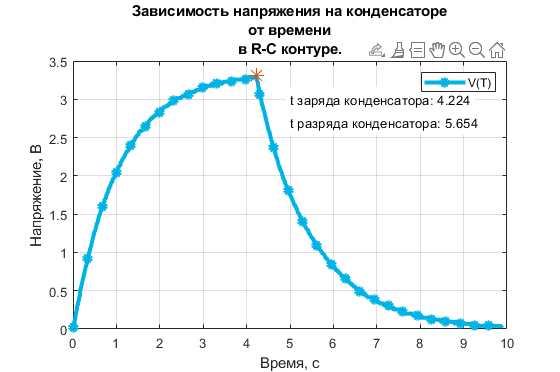

VfromT = figure ();
plot (T, V, '-o', "MarkerIndices", 1:30:length(V), "LineWidth", 3, "MarkerSize", 5, 'Color',[0,0.7,0.9])
hold on
plot (maxT, maxV, '*', "MarkerSize", 10)
grid on
title ({'Зависимость напряжения на конденсаторе' 'от времени' 'в R-C контуре.'})
xlabel ("Время, с")
ylabel ("Напряжение, В")
legend ("V(T)")
text (5, 3, "t заряда конденсатора: " + T1, "BackgroundColor", "w")
text (5, 2.7, "t разряда конденсатора: " + T2, "BackgroundColor", "w")
saveas (VfromT, "конденсатор.png")
saveas (VfromT, "capacitor.svg")
set (gcf, 'Visible', 'on', "Name", "Романос Мкртчян Б03-008д")